clear
clf
newcolor = [228 26 28
            55 126 184
            77 175 74
            152 78 163
            255 127 0]/255

newcolor =     0.8941    0.1020    0.1098
    0.2157    0.4941    0.7216
    0.3020    0.6863    0.2902
    0.5961    0.3059    0.6392
    1.0000    0.4980         0


colororder(newcolor);

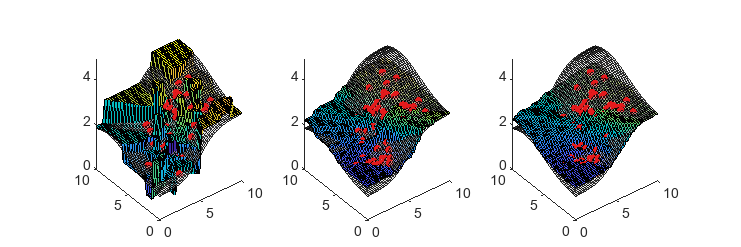

rng(1)
fig = figure(); 
fig.Position(3:4) = [900, 300];

N = 80;
M = 50;
K = 50;

fz = @(x) 2 + tanh(0.5*(x(:,1)-5)) + exp(-(x(:,2) - 8).^2/20);

XFull = [mvnrnd([2;3], [2, 0.1; 0.1, 2.5], M*N/2);
     mvnrnd([4;1], [1, -0.5; -0.5, 2], M*N/4);
     mvnrnd([0;0], [0.5, 0; 0, 0.5], M*N/4);] + [3 2];
zFull = fz(XFull) + 0.5*randn(N*M,1);

C = cvpartition(N*M, 'KFold', M);


NG = 50;
[xG, yG] = meshgrid(linspace(0,10,NG));
zG = reshape(fz([reshape(xG,[],1), reshape(yG,[],1)]), NG, []);

Nk = 50;
[xk, yk] = meshgrid(linspace(0,10,Nk));
    

for i = 1:M
    X = XFull(C.test(i),:);
    z = zFull(C.test(i));
    
    subplot(1,3,1)
    K = 1;
    zk = reshape(kNN([reshape(xk,[],1), reshape(yk,[],1)], X, z, K), Nk, []);
    
    hold off
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    surf(xk, yk, zk)
    axis([0 10 0 10 0 5]); %axis square

    subplot(1,3,2)
    K = 10;
    zk = reshape(kNN([reshape(xk,[],1), reshape(yk,[],1)], X, z, K), Nk, []);
    
    hold off
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    surf(xk, yk, zk)
    axis([0 10 0 10 0 5]); %axis square

    subplot(1,3,3)
    K = 20;
    zk = reshape(kNN([reshape(xk,[],1), reshape(yk,[],1)], X, z, K), Nk, []);
    
    hold off
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    surf(xk, yk, zk)
    axis([0 10 0 10 0 5]); %axis square

    drawnow
end

K = 40;
MSE = zeros(M,K);
for k = 1:K
    for i = 1:M
        X = XFull(C.test(i),:);
        z = zFull(C.test(i));
    
        zk = kNN(XFull(C.training(i),:), X, z, k)';
        MSE(i,k) = mean( (zk - zFull(C.training(i))).^2 );
    end
end

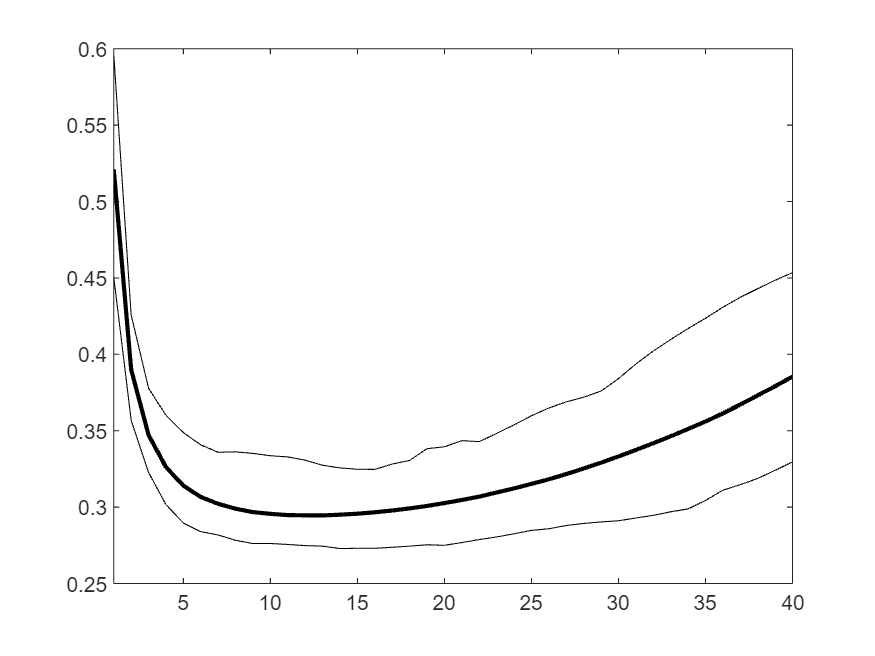

figure
hold off
p = plot(1:K, mean(MSE,1),'k', ...
         1:K, prctile(MSE, 5),'k',...
         1:K, prctile(MSE, 95),'k');
p(1).LineWidth = 2;
axis([1 K 0.25 0.6])

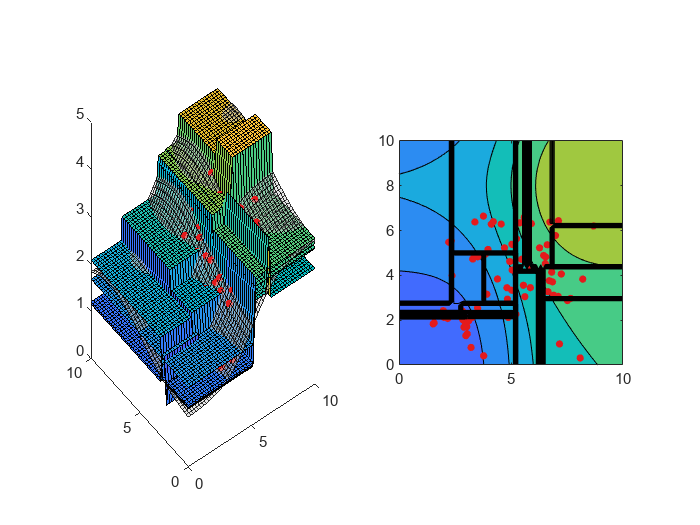

K = 20;

i = 3;
X = XFull(C.test(i),:);
z = zFull(C.test(i));
figure
for k = 1:K
    %Mdl = fitrtree(X,z,'MinLeafSize',k,'MaxNumSplits',200,'MinParentSize',2);
    Mdl = fitrtree(X,z,'MinLeafSize',1,'MaxNumSplits',k,'MinParentSize',2);
    zk = reshape(predict(Mdl, [reshape(xk,[],1), reshape(yk,[],1)]), Nk, []);
    
    subplot(1,2,1)
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    surf(xk, yk, zk)
    axis([0 10 0 10 0 5]); %axis square
    caxis([0 5]);

    subplot(1,2,2)
    s = contourf(xG,yG,zG);
    %s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    
    hold on
    p = plot(X(:,1), X(:,2), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    [~,c] = contour(xk, yk, zk, linspace(0,5,200));
    c.LineColor = 'k';
    axis([0 10 0 10 0 5]); axis square
    caxis([0 5]);
    drawnow
end

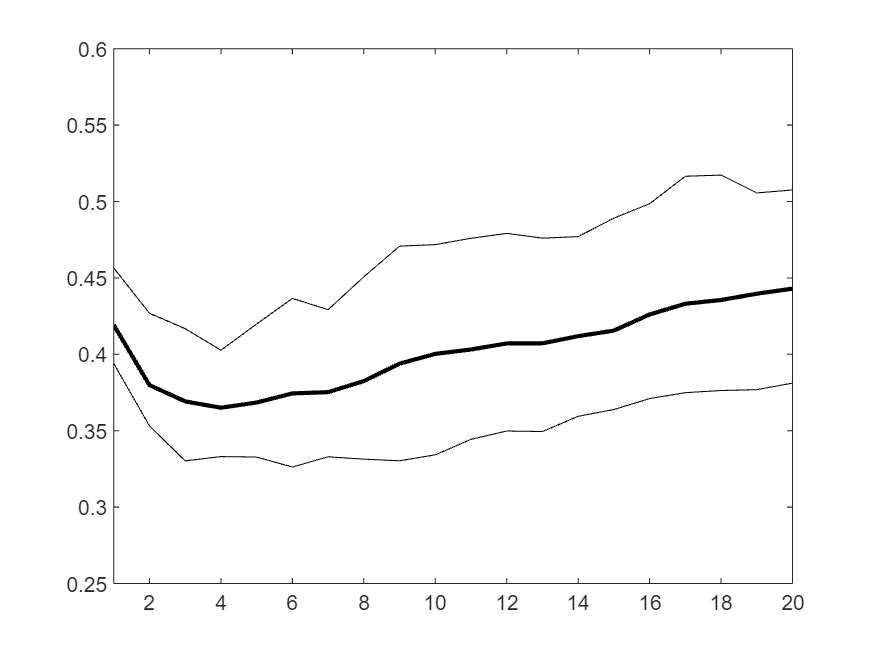

MSE = zeros(M,K);
for k = 1:K
    for i = 1:M
        X = XFull(C.test(i),:);
        z = zFull(C.test(i));
    
        Mdl = fitrtree(X,z,'MinLeafSize',1,'MaxNumSplits',k,'MinParentSize',2);
        zk = predict(Mdl, XFull(C.training(i),:));
        MSE(i,k) = mean( (zk - zFull(C.training(i))).^2 );
    end
end

figure
hold off
p = plot(1:K, mean(MSE,1),'k', ...
         1:K, prctile(MSE, 5),'k',...
         1:K, prctile(MSE, 95),'k');
p(1).LineWidth = 2;
axis([1 K 0.25 0.6])

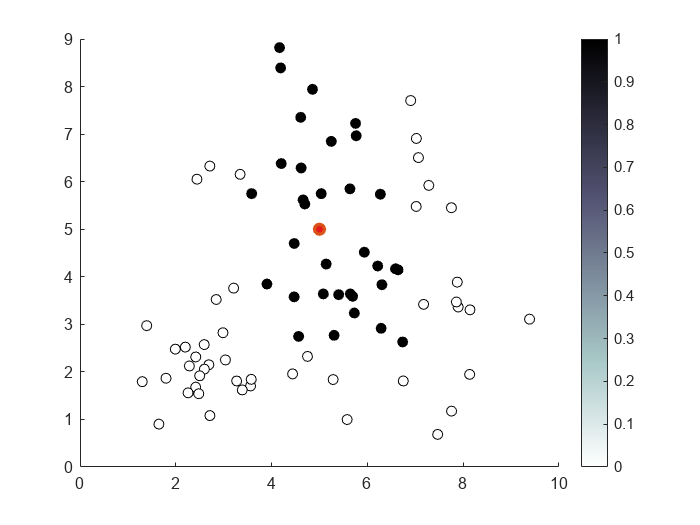

% Determine the data on same leaf
i = 4;
X = XFull(C.test(i),:);
z = zFull(C.test(i));

k = 5;
learners = 100;
Mdl = fitrtree(X,z,'MinLeafSize',1,'MaxNumSplits',k,'MinParentSize',2);
zD = resubPredict(Mdl);
z0 = predict(Mdl, [5 5]);
I = find(zD == z0);
sens = zeros(N,1); sens(I) = 1;

figure
colormap(flipud(colormap('bone')));
hold off
scatter(X(:,1), X(:,2),[],sens,'MarkerFaceColor','flat', 'MarkerEdgeColor','k')
caxis([0 1])
hold on
plot(5,5,'o','LineWidth',2,'MarkerFaceColor',newcolor(1,:));
colorbar

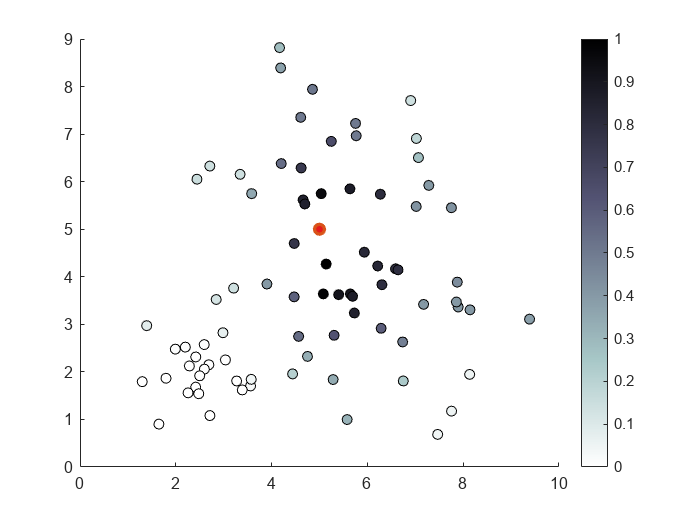


template = templateTree('MinLeafSize',1,'MaxNumSplits',k,'MinParentSize',2);
Mdl = fitrensemble(X,z,'Method','Bag','Learner',template,'NumLearningCycles', learners);
sens_mat = zeros(learners, N);
for j = 1:learners
    subMdl = Mdl.Trained{j};
    zD = predict(subMdl, X);
    z0 = predict(subMdl, [5 5]);
    I = find(zD == z0);
    sens_mat(j, I) = 1;
end
sens = sum(sens_mat, 1); sens = sens/max(sens);

figure
colormap(flipud(colormap('bone')));
hold off
scatter(X(:,1), X(:,2),[],sens,'MarkerFaceColor','flat', 'MarkerEdgeColor','k')
caxis([0 1])
hold on
plot(5,5,'o','LineWidth',2,'MarkerFaceColor',newcolor(1,:));
colorbar

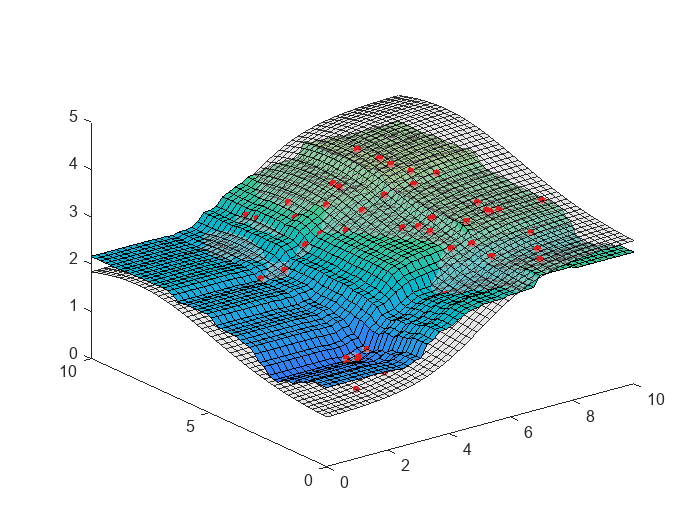

zk = reshape(predict(Mdl, [reshape(xk,[],1), reshape(yk,[],1)]), Nk, []);

figure
p = plot3(X(:,1), X(:,2), fz(X), '.');
p.MarkerSize = 15; p.Color = newcolor(1,:);
hold on
s = surf(xG,yG,zG);
s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
surf(xk, yk, zk)
axis([0 10 0 10 0 5]); %axis square
caxis([0 5]);

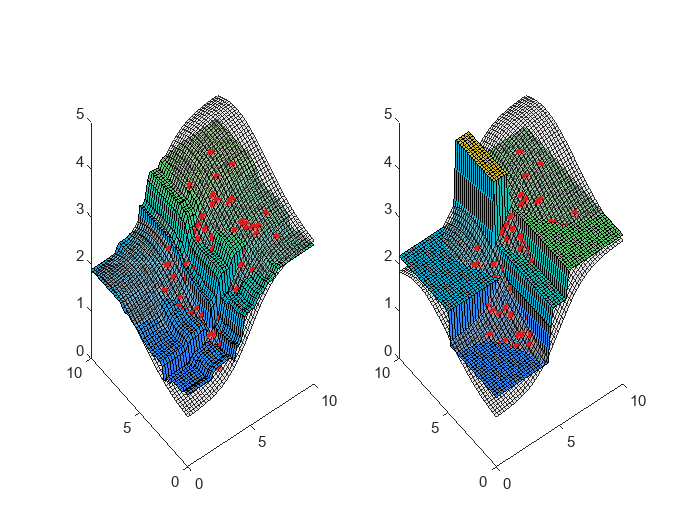

figure
for i = 1:50
    X = XFull(C.test(i),:);
    z = zFull(C.test(i));

    Mdl = fitrensemble(X,z,'Method','Bag','Learner',template,'NumLearningCycles', learners);
    zk = reshape(predict(Mdl, [reshape(xk,[],1), reshape(yk,[],1)]), Nk, []);
    
    subplot(1,2,1)
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    surf(xk, yk, zk)
    axis([0 10 0 10 0 5]); %axis square
    caxis([0 5]);
    hold off
    drawnow


    Mdl = fitrtree(X,z,'MinLeafSize',1,'MaxNumSplits',k,'MinParentSize',2);
    zk = reshape(predict(Mdl, [reshape(xk,[],1), reshape(yk,[],1)]), Nk, []);
    
    subplot(1,2,2)
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    surf(xk, yk, zk)
    axis([0 10 0 10 0 5]); %axis square
    caxis([0 5]);
    hold off
    drawnow
end

function y = kNN(x, xData, yData, K)
    D = pdist2(x, xData);
    [~, I] = sort(D, 2);
    for i = 1:length(x)
        y(i) = mean(yData(I(i, 1:K)));
    end
end